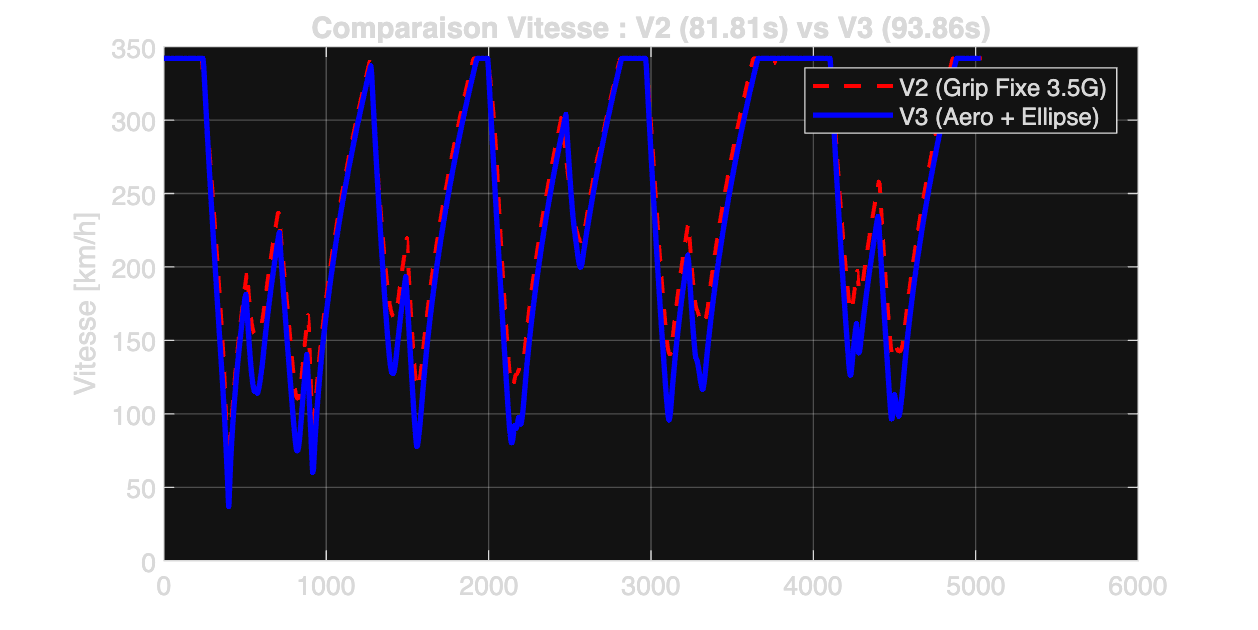

clear; clc; close all;

% Charger les fichiers PROPRES
try
    v2 = load('DATA_V2_PURE.mat');
    v3 = load('DATA_V3_PURE.mat');
catch
    error('Les fichiers .mat ne sont pas trouvés. Lance V2 puis V3 avec les codes de sauvegarde.');
end

% Préparer les axes X (Distance cumulée)
% Attention : Comme la trajectoire géométrique change un peu entre V2 et V3, 
% les distances totales ne sont pas exactement les mêmes au mètre près.
dist_v2 = [0; cumsum(v2.ds(1:end-1))];
dist_v3 = [0; cumsum(v3.ds(1:end-1))];

% FIGURE DE BATAILLE
figure('Name','V2 vs V3 Final Battle', 'Color', 'w', 'Position', [100 100 1200 600]);

% 1. Profil de Vitesse
plot(dist_v2, v2.v_final*3.6, 'r--', 'LineWidth', 1.5, 'DisplayName', 'V2 (Grip Fixe 3.5G)');
hold on;
plot(dist_v3, v3.v_final*3.6, 'b-', 'LineWidth', 2, 'DisplayName', 'V3 (Aero + Ellipse)');
ylabel('Vitesse [km/h]'); grid on;
legend; title(['Comparaison Vitesse : V2 (' num2str(v2.t_final,'%.2f') 's) vs V3 (' num2str(v3.t_final,'%.2f') 's)']);